Clean test time: 106.0 s


Accuracy: 98.59%
Precision: 97.64%  Recall: 98.54%  F1: 98.08%


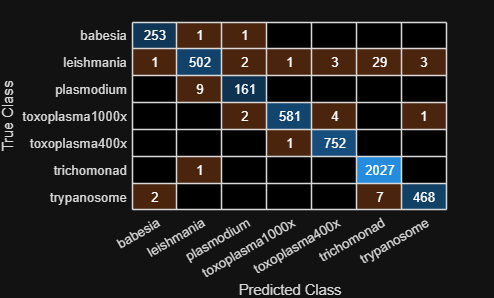

Error using perfcurve (line 1)
Invalid argument name 'positive'. Name must be one of these:
    'NegClass'
    'XCrit'
    'YCrit'
    'XVals'
    'TVals'
    'UseNearest'
    'ProcessNaN'
    'Prior'
    'Cost'
    'Weights'
    'NBoot'
    'BootType'
    'BootArg'
    'Alpha'
    'Options'
    'ExtendedPRAUC'

%% Load trained model
load('D:\LocalUser\42177 Project\artifacts\cnn_model.mat', 'net', 'classes');

%% Recreate datastores for test set
rootClean = 'D:\LocalUser\42177 Project\data\clean';
imdsTest  = imageDatastore(fullfile(rootClean,'test'), ...
    "IncludeSubfolders", true, "LabelSource", "foldernames");
adsTest   = augmentedImageDatastore([256 256 3], imdsTest);

%% Evaluate on clean test set
t1 = tic;
[YPred, ~] = classify(net, adsTest);
testSecs = toc(t1);
fprintf('Clean test time: %.1f s\n', testSecs);

y_true = string(imdsTest.Labels);
y_pred = string(YPred);

%% Evaluate model
results = evaluate_model(y_true, y_pred, string(classes));

%% Save results as .csv
artifactsDir = 'D:\LocalUser\42177 Project\artifacts';
if ~exist(artifactsDir, 'dir')
    mkdir(artifactsDir);
end

% Convert confusion matrix to table and save
confMatTable = array2table(results.ConfusionMatrix, ...
    'VariableNames', results.Labels, ...
    'RowNames', results.Labels);
writetable(confMatTable, fullfile(artifactsDir, 'results_cnn_confmx.csv'), 'WriteRowNames', true);

% Save summary metrics (accuracy, precision, recall, etc.)
summaryTable = struct2table(rmfield(results, {'ConfusionMatrix','Labels'}));
summaryTable.TestTime = testSecs;
writetable(summaryTable, fullfile(artifactsDir, 'results_cnn_clean.csv'));

fprintf('Results saved to CSV in %s\n', artifactsDir);

%% Display confusion matrix
confusionchart(results.ConfusionMatrix, results.Labels);

%% Evaluate CNN on degraded test sets with progress and timing
rootDeg      = 'D:\LocalUser\42177 Project\data\degraded';
artifactsDir = 'D:\LocalUser\42177 Project\artifacts';
if ~exist(artifactsDir, 'dir'), mkdir(artifactsDir); end

% List all degradation condition folders
dinfo = dir(rootDeg);
conds = {dinfo([dinfo.isdir]).name};
conds = conds(~ismember(conds, {'.','..'}));

fprintf('Evaluating CNN on %d degraded conditions...\n', numel(conds));

Evaluating CNN on 10 degraded conditions...



% Create progress bar
h = waitbar(0, 'Starting degraded tests...');
ticTotal = tic;

for ci = 1:numel(conds)
    cond = conds{ci};
    degTestDir = fullfile(rootDeg, cond, 'test');

    % Skip if folder missing or empty
    if ~isfolder(degTestDir)
        fprintf('Skip %s: no test folder.\n', cond);
        continue
    end
    imdsDeg = imageDatastore(degTestDir, "IncludeSubfolders", true, "LabelSource", "foldernames");
    if numel(imdsDeg.Files) == 0
        fprintf('Skip %s: no image files.\n', cond);
        continue
    end

    % Create datastore for this degradation condition
    adsDeg = augmentedImageDatastore([256 256 3], imdsDeg);

    % --- Run classification ---
    tDeg = tic;
    [YPredDeg, ~] = classify(net, adsDeg);
    testSecsDeg = toc(tDeg);

    % Prepare labels
    y_true = string(imdsDeg.Labels);
    y_pred = string(YPredDeg);

    % Evaluate metrics
    resDeg = evaluate_model(y_true, y_pred, string(classes));

    % --- Save results ---
    confMatTable = array2table(resDeg.ConfusionMatrix, ...
        'VariableNames', resDeg.Labels, ...
        'RowNames',     resDeg.Labels);
    writetable(confMatTable, fullfile(artifactsDir, sprintf('results_cnn_%s_confmx.csv', cond)), ...
        'WriteRowNames', true);

    summaryTable = struct2table(rmfield(resDeg, {'ConfusionMatrix','Labels'}));
    summaryTable.TestTimeSeconds = testSecsDeg;
    writetable(summaryTable, fullfile(artifactsDir, sprintf('results_cnn_%s.csv', cond)));

    % --- Progress & time display ---
    elapsed = toc(ticTotal);
    est_total = elapsed / ci * numel(conds);
    remaining = max(0, est_total - elapsed);
    msg = sprintf('Condition %d/%d: %s | Time: %.1fs | Remaining: %.1fs', ...
                  ci, numel(conds), cond, elapsed, remaining);
    waitbar(ci/numel(conds), h, msg);

    fprintf('[%d/%d] %s done (%.1f s). Elapsed: %.1f s, Remaining: %.1f s\n', ...
            ci, numel(conds), cond, testSecsDeg, elapsed, remaining);
end

Accuracy: 98.57%
Precision: 97.61%  Recall: 98.53%  F1: 98.05%


[1/10] gaussian_blur_s1.0 done (164.2 s). Elapsed: 165.4 s, Remaining: 1488.4 s


Accuracy: 98.55%
Precision: 97.60%  Recall: 98.50%  F1: 98.04%


[2/10] gaussian_blur_s2.0 done (169.0 s). Elapsed: 335.2 s, Remaining: 1340.9 s


Accuracy: 31.32%
Precision: 35.48%  Recall: 40.52%  F1: 23.07%


[3/10] gaussian_noise_s15 done (164.1 s). Elapsed: 500.5 s, Remaining: 1167.9 s


Accuracy: 92.75%
Precision: 91.70%  Recall: 91.78%  F1: 91.49%


[4/10] gaussian_noise_s5 done (157.4 s). Elapsed: 658.9 s, Remaining: 988.3 s


Accuracy: 97.61%
Precision: 97.10%  Recall: 97.17%  F1: 97.13%


[5/10] jpeg_q20 done (165.3 s). Elapsed: 824.8 s, Remaining: 824.8 s


Accuracy: 98.57%
Precision: 97.55%  Recall: 98.50%  F1: 98.01%


[6/10] jpeg_q40 done (165.1 s). Elapsed: 991.2 s, Remaining: 660.8 s


Accuracy: 98.67%
Precision: 97.82%  Recall: 98.53%  F1: 98.17%


[7/10] jpeg_q60 done (161.3 s). Elapsed: 1153.3 s, Remaining: 494.3 s


Accuracy: 98.57%
Precision: 97.61%  Recall: 98.53%  F1: 98.05%


[8/10] motion_blur_k5 done (154.3 s). Elapsed: 1308.0 s, Remaining: 327.0 s


Accuracy: 98.57%
Precision: 97.61%  Recall: 98.53%  F1: 98.05%


[9/10] resolution_x2 done (174.3 s). Elapsed: 1482.9 s, Remaining: 164.8 s


Accuracy: 98.57%
Precision: 97.63%  Recall: 98.51%  F1: 98.06%


[10/10] resolution_x4 done (172.3 s). Elapsed: 1655.8 s, Remaining: 0.0 s



close(h);
totalTime = toc(ticTotal);
fprintf('All degraded tests completed in %.1f seconds (%.1f min).\n', ...
        totalTime, totalTime/60);

All degraded tests completed in 1657.4 seconds (27.6 min).
